## Import unicycle library

clear
addpath ~/Dropbox/scripts/utils/
addpath ../unicycle/matlab/
import unicycle.*

This will make the unicycle libraries available to MATLAB's 'path'.

Set elastic properties and store it in a unicycle object

G = 30e3;% in MPa
nu = 0.25;
earthModel = unicycle.greens.okada92(G,nu);

Specify fault names

f1name = 'f1.seg';
f2name = 'f2.seg';

Read the faults in unicycle objects

f1 = unicycle.geometry.receiver(f1name,earthModel);
f2 = unicycle.geometry.receiver(f2name,earthModel);

## Visualize fault geometries

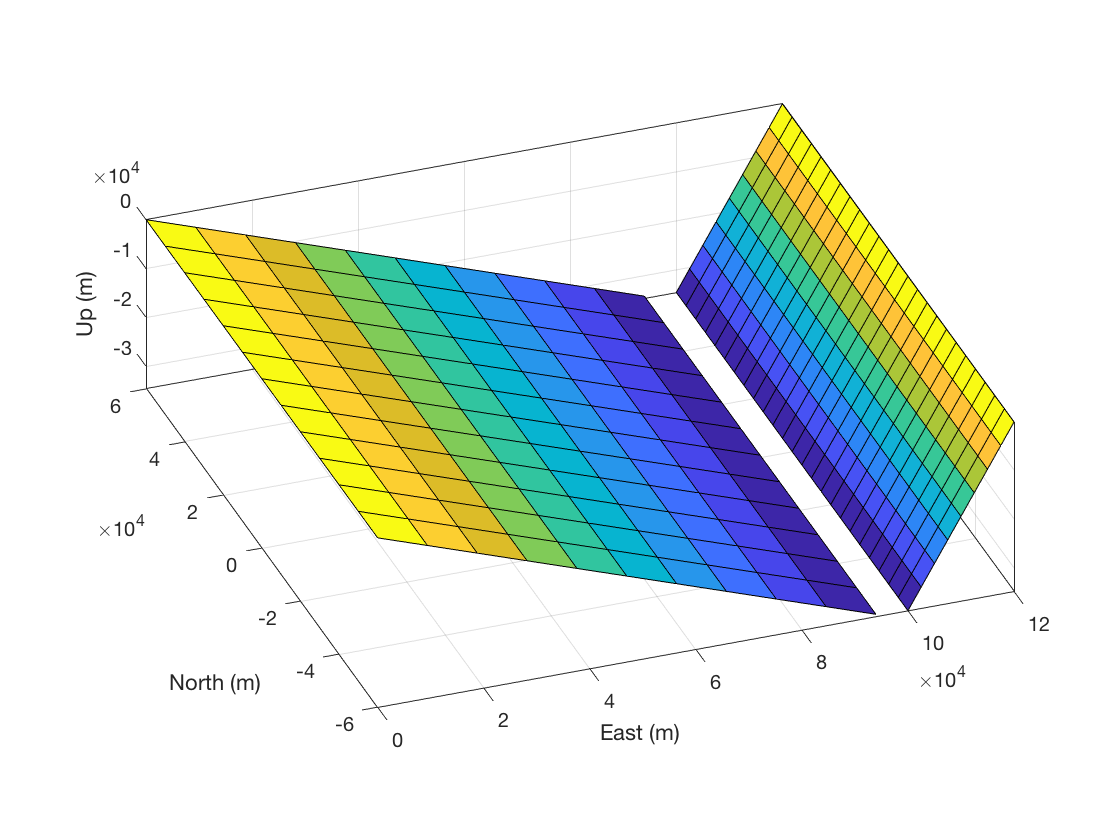

figure(1),clf
f1.plotPatch(f1.xc(:,3)), hold on, shading faceted
f2.plotPatch(f2.xc(:,3)), shading faceted
axis tight equal, box on, grid on
xlabel('East (m)'),ylabel('North (m)'), zlabel('Up (m)')
view(-20,30)

## Computing displacements and stresses using Okada92

First create a grid

n2 = 60;
n3 = 20;

x2 = linspace(-0e3,100e3,n2);
x3 = linspace(-35e3,-0.1,n3);
[X2,X3] = meshgrid(x2,x3);

Now choose a fault patch and compute the stress and dispalcements due to slip on this patch in either to 's' or 'd' directions

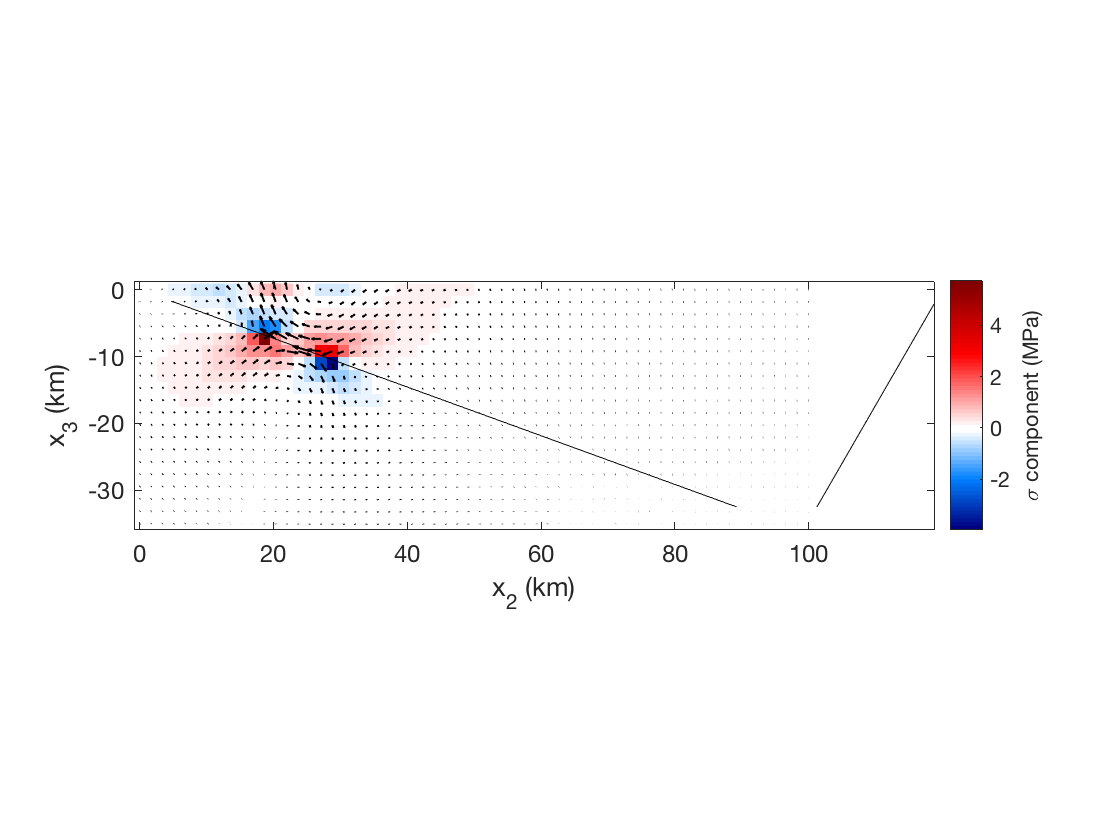

k = 30;
% compute distance from top left corner
xd=X2(:)-f1.x(k,1);
yd=X2(:).*0 -f1.x(k,2);
zd=X3(:);    

nel = numel(X2);
% U - 3-component displacement field
% S - 6-component stress field
[U,~,~,S] = unicycle.greens.computeOkada92(1,xd(:),yd(:),zd(:),G,nu, ...
        -f1.x(k,3),f1.dip(k)/180*pi,f1.L(k),f1.W(k),'d',0,f1.strike(k)/180*pi);
S=reshape(S,nel,3,3);
U=reshape(U,nel,3);

% compute displacement components
u1 = U(:,1);
u2 = U(:,2);
u3 = U(:,3);

% compute stress components
S11 = S(:,1,1);
S12 = S(:,1,2);
S13 = S(:,1,3);
S22 = S(:,2,2);
S23 = S(:,2,3);
S33 = S(:,3,3);

figure(1),clf
imagesc(x2./1e3,x3./1e3,reshape(S11,n3,n2)), hold on
plot(f1.xc(:,1)./1e3,f1.xc(:,3)./1e3,'k-')
plot(f2.xc(:,1)./1e3,f2.xc(:,3)./1e3,'k-')
quiver(X2(:)./1e3,X3(:)./1e3,u1,u3,'k-','LineWidth',1)
axis tight equal
colormap bluewhitered
cb=colorbar;cb.Label.String='\sigma component (MPa)';
xlabel('x_2 (km)'),ylabel('x_3 (km)')
set(gca,'YDir','normal','FontSize',12)

## Unicycle to compute displacements and stresses

Observations at the free surface and displacement kernels

Gs - 3-component displacement kernel due to strike-slip

Gd - 3-component displacement kernel due to dip-slip

ox = linspace(-50e3,150e3,200)';
[Gs,Gd] = f1.displacementKernels([ox,ox.*0,ox.*0],3);
% traction kernels
[~,Kds12,~,Kdd12,~,~] = f1.tractionKernels(f2);

# rectangle traction kernels: 100%    [..........]


[~,Kds11,~,Kdd11,~,~] = f1.tractionKernels(f1);

# rectangle traction kernels: 100%    [..........]


Compute displacements and tractions with known slip distribution

% start with Gd
Ge = Gd(1:3:end,:);
Gz = Gd(3:3:end,:);
Gn = Gd(2:3:end,:);

slip = zeros(f1.N,1);
index = f1.xc(:,1)>=10e3 & f1.xc(:,1)<=80e3 & abs(f1.xc(:,2))<= 30e3;
slip(index) = 1;


Calculating the resulting displacement field due to slip

ue = Ge*slip;
un = Gn*slip;
uz = Gz*slip;

## Calculating traction changes

In a 3-d problem $t_d = K_{dd}.s_{dip} + K_{sd}.s_{strike}$

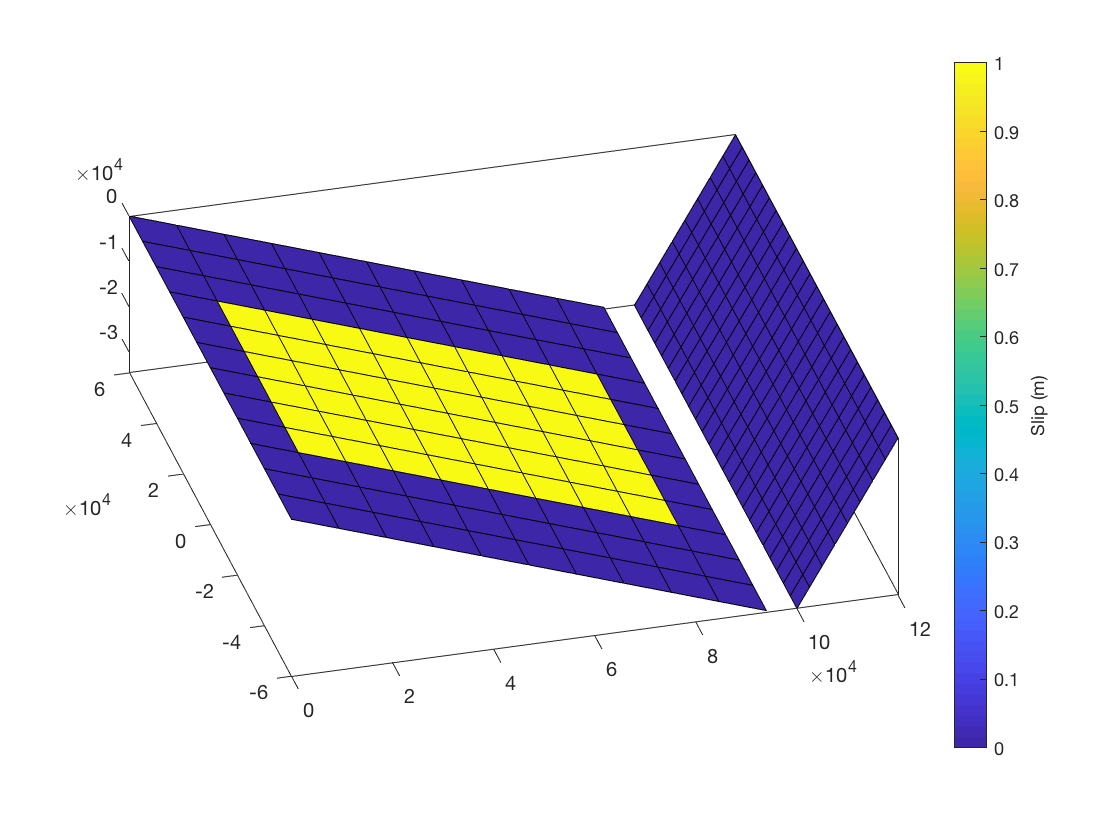

td2 = Kdd12*slip;
ts2 = Kds12*slip;
td1 = Kdd11*slip;
ts1 = Kds11*slip;

figure(1),clf
f1.plotPatch(slip), shading faceted, hold on
f2.plotPatch(zeros(f2.N,1)), shading faceted
cb=colorbar;cb.Label.String = 'Slip (m)';
colormap parula
axis tight equal, box on
view(-15,30)

## Plot surface displacements

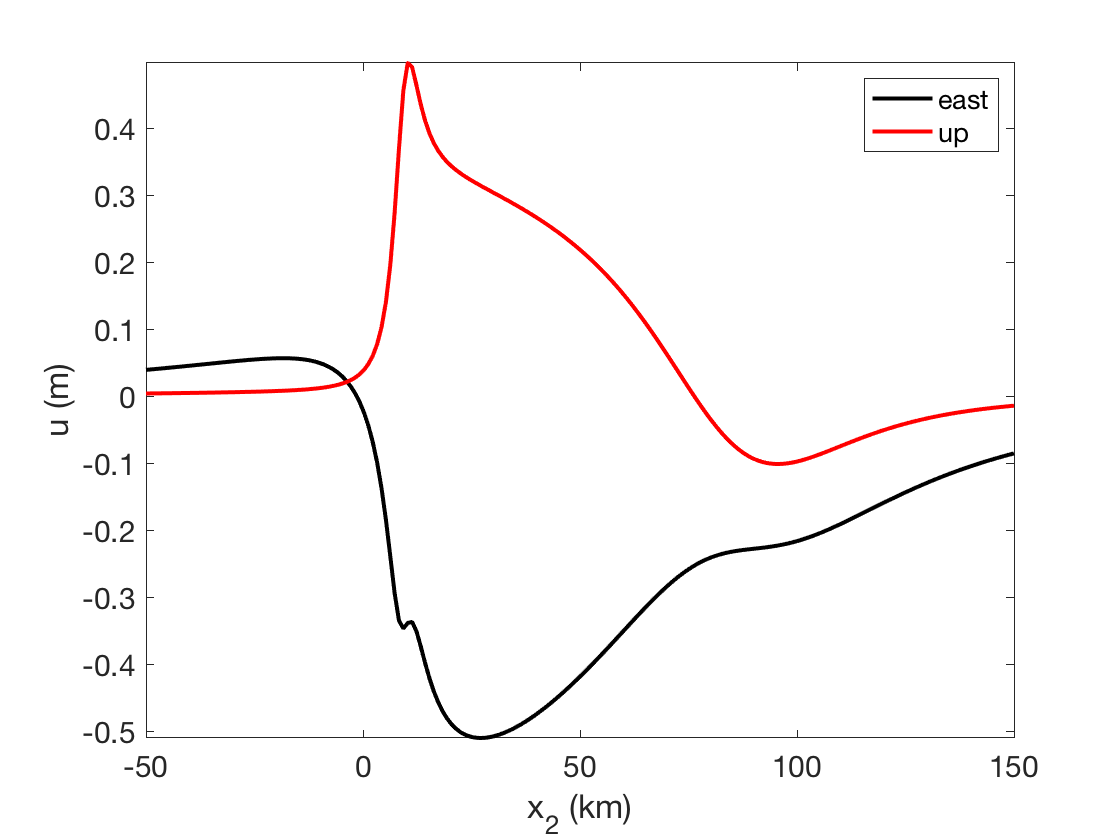

figure(2),clf
plot(ox./1e3,ue,'k-','LineWidth',2), hold on
plot(ox./1e3,uz,'r-','LineWidth',2)
axis tight
legend('east','up')
xlabel('x_2 (km)'),ylabel('u (m)')
set(gca,'Fontsize',15)

Plot tractions on F2 due to slip on F1

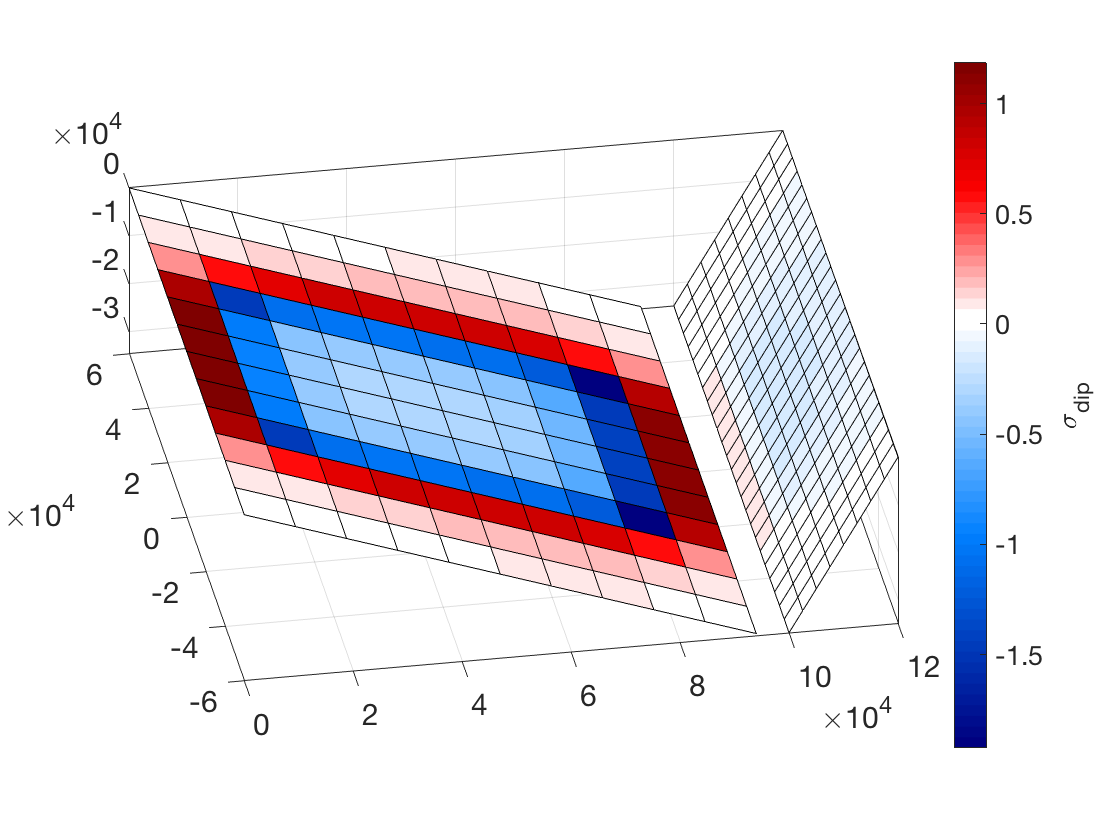

figure(3),clf
f1.plotPatch(td1), hold on
f2.plotPatch(td2), shading faceted
axis tight equal, box on, grid on
cb=colorbar;
cb.Label.String = '\sigma_{dip}';
view(-10,30)
colormap bluewhitered
set(gca,'Fontsize',15)

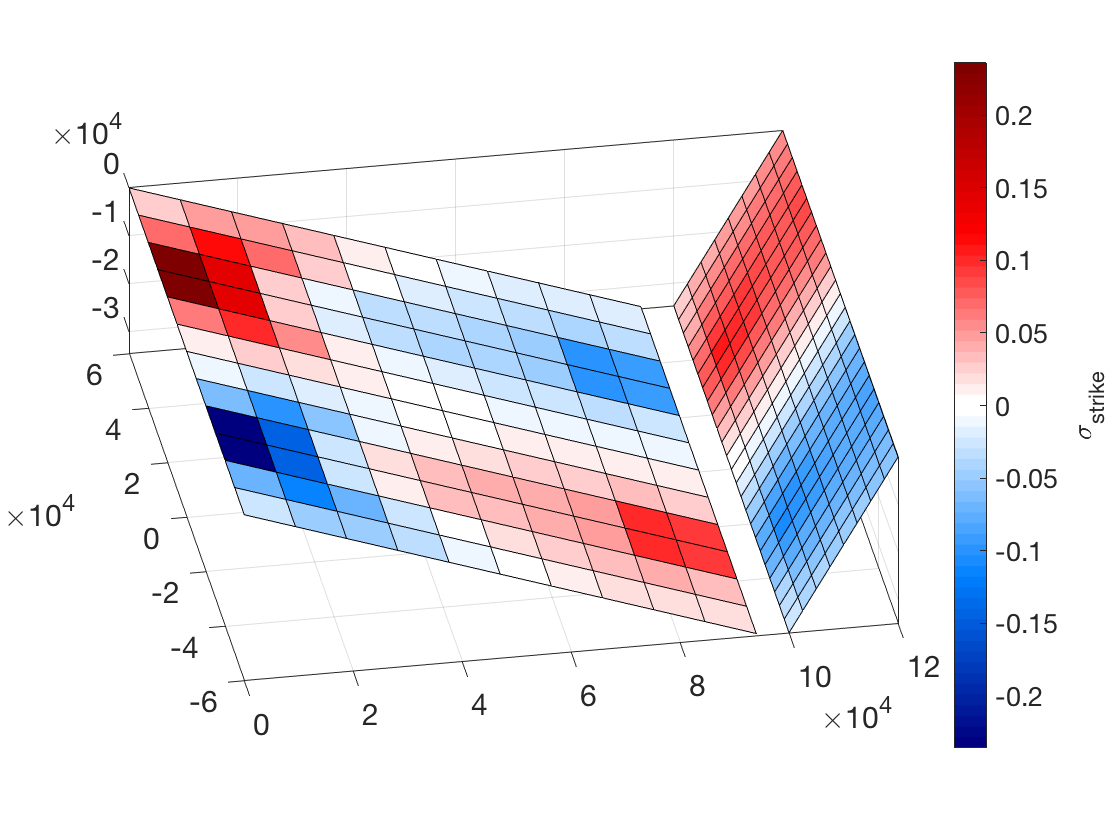


figure(4),clf
f1.plotPatch(ts1), hold on
f2.plotPatch(ts2), shading faceted
axis tight equal, box on, grid on
cb=colorbar;
cb.Label.String = '\sigma_{strike}';
view(-10,30)
set(gca,'Fontsize',15)
colormap bluewhitered